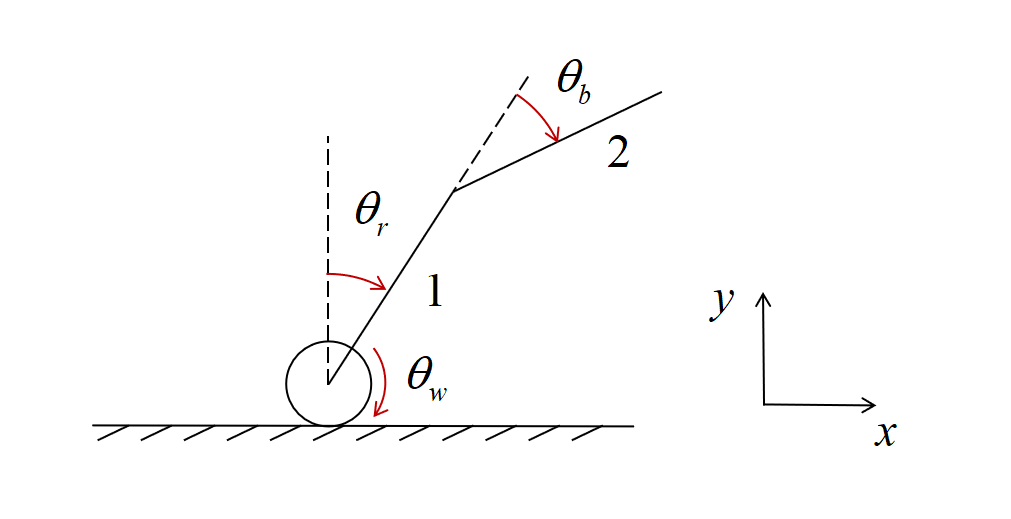

syms theta_r theta_w theta_b % Rod1 inclination angle (angle of rod1 relative to world frame), rear wheel rotation angle (rear wheel angle relative to rod1), waist angle (rod2 angle relative to rod1)
syms theta_dot_r theta_dot_w theta_dot_b theta_ddot_r theta_ddot_w theta_ddot_b
syms m_1 I_1 m_r I_r m_2 I_2 
syms g r l_1 l_2 d_1 d_2 % l_i: rod length; d_i: center of mass position of rod

q = [theta_r;theta_b;theta_w];
dq = [theta_dot_r;theta_dot_b;theta_dot_w];
ddq = [theta_ddot_r;theta_ddot_b;theta_ddot_w];

car_params = [m_1 m_2 m_r g I_1 I_2 I_r l_1 l_2 r d_1 d_2];
states = [q;dq].';

% Assume the rear wheel rolls purely without slipping
% Rear wheel position, velocity, and energy
xw = [r*(theta_r+theta_w);
      0;
      theta_r+theta_w];
vw = jacobian(xw,q)*dq;
Tw = 0.5*m_r*vw(1:2).'*vw(1:2) + 0.5*I_r*vw(3)^2;
Uw = m_r*g*xw(2);

% Center of mass position, velocity, and energy of the lower body
x1 = [r*(theta_r+theta_w)+d_1*sin(theta_r);
      d_1*cos(theta_r);
      theta_r];
v1 = jacobian(x1,q)*dq;
T1 = 0.5*m_1*v1(1:2).'*v1(1:2) + 0.5*I_1*v1(3)^2;
U1 = m_1*g*x1(2);

% Center of mass position, velocity, and energy of the upper body
x2 = [r*(theta_r+theta_w)+l_1*sin(theta_r)+d_2*sin(theta_r+theta_b);
      l_1*cos(theta_r)+d_2*cos(theta_r+theta_b);
      theta_r+theta_b];
v2 = jacobian(x2,q)*dq;
T2 = 0.5*m_2*v2(1:2).'*v2(1:2) + 0.5*I_2*v2(3)^2;
U2 = m_2*g*x2(2);

L = Tw+T1+T2-Uw-U1-U2;
Jq = jacobian(L,q).';
Jdq = jacobian(L,dq).';
Jdqdt = jacobian(Jdq,dq)*ddq + jacobian(Jdq,q)*dq;

% M*ddq + b = 0
M = simplify(jacobian(Jdq,dq));
b = simplify(jacobian(Jdq,q)*dq - Jq);

syms fr fb % rear wheel motor torque, waist motor torque
Q = [0;fb;fr];

u = [fb; fr];
% M*ddq + b = Q
eqn = M*ddq + b == Q;


EL = M*ddq + b - Q;     % = 0 gives equations of motion

% Solve for accelerations ddq = [ddx; ddth]
sol = solve(EL == 0, ddq);
ddr_expr = simplify(sol.theta_ddot_r);
ddb_expr  = simplify(sol.theta_ddot_b);
ddw_expr = simplify(sol.theta_ddot_w);

% --- Build nonlinear state-space: X=[x;dx;th;dth]
f = [
    theta_dot_r;
    ddr_expr;
    theta_dot_b;
    ddb_expr;
    theta_dot_w;
    ddw_expr
];
g_u = jacobian(f, u)   % input channel (should be a 4x1)



% --- Linearize around upright equilibrium: x=0, dx=0, th=0, dth=0, Q=0
xeq = [0; 0; 0; 0; 0; 0];
ueq = [0; 0];

A = simplify( subs( jacobian(f, [theta_b, theta_dot_b, theta_r, theta_dot_r,theta_w, theta_dot_w]), ...
    [theta_b, theta_dot_b, theta_r, theta_dot_r,theta_w, theta_dot_w, u], [xeq.', ueq.'] ) );

错误使用 catMany>checkDimensions (第 53 行)
Dimensions of objects being concatenated must match.

出错 catMany (第 12 行)
[resz, ranges] = checkDimensions(sz, dim);

出错 sym

B = simplify( subs( g_u, [theta_b, theta_dot_b, theta_r, theta_dot_r,theta_w, theta_dot_w, u], [xeq.', ueq] ) );

% --- Optional: pretty-print A, B
disp('A ='); pretty(A); disp('B ='); pretty(B);

% --- Verification: simplify A and B to common forms 
A_simplified = simplify(A)
B_simplified = simplify(B)

% Center of mass of the two-link part
mc = m_1+m_2;
pc = simplify((m_1*x1(1:2) + m_2*x2(1:2))/mc - xw(1:2));% COM position relative to the rear wheel
thetac = atan(pc(1)/pc(2));
xc = [pc;thetac]
simplify(xc(1)^2+xc(2)^2);
lc = simplify(norm(pc))
% Inertia
Ic = simplify(I_1+m_1*norm(x1(1:2)-xw(1:2)-pc)^2 ...
    + I_2 + m_2*norm(x2(1:2)-xw(1:2)-pc)^2);
vc = simplify(jacobian(xc,q)*dq);

matlabFunction(mc,Ic,xc,vc,...
    'file','modelcom11111.m',...
    'vars',{states,car_params},...
    'outputs',{'mc','Ic','xc','vc'});

% % Compute the support force
% syms fr fb % rear wheel motor torque, waist motor torque
% Q = [0;fb;fr];
% % ddq = M^{-1} * (-b+Q)
% ddq_fun = M\(-b+Q);
% 
% % Acceleration
% a1 = jacobian(v1,q)*dq + jacobian(v1,dq)*ddq_fun;
% a2 = jacobian(v2,q)*dq + jacobian(v2,dq)*ddq_fun;
% 
% 
% N = simplify(m_1*g+m_2*g + m_1*a1(2) + m_2*a2(2)); % rear wheel is ignored
% N = collect(N,[fr,fb]);
% % matlabFunction(N,...
% %     'file','N.m',...
% %     'vars',{states,fr,fb,car_params},...
% %     'outputs',{'N'});
% coef_b = simplify(jacobian(N,fb));
% % matlabFunction(coef_b,...
% %     'file','coef_waist_torque.m',...
% %     'vars',{states,car_params},...
% %     'outputs',{'coef_b'});
% pcpr = simplify(jacobian(coef_b,theta_r));
% % matlabFunction(pcpr,...
% %     'file','pitch_pos_cal.m',...
% %     'vars',{states,car_params},...
% %     'outputs',{'pcpr'});